# Project MSB1015: Ayahuasca

## Script 6: Unsupervised Random Forest (URF)

## Guus Wilmink, i6156211

## Load data

clear all; close all;

% Add Fieldtrip toolbox, gscatter3 and kernel PCA
addpath('./fieldtrip-20220912');
addpath('./gscatter3');
addpath('./KernelPCA');

% Load the data
load('.\processed_1_30Hz.mat');
load('.\processed_30_100Hz.mat');
elec = load(".\freqs_1-30Hz.mat").data_all_mean.elec;

% Specify bands
delta=2.5; theta=6; alpha=10.5; beta=21.5; slowgamma=40; fastgamma=75;

**Select frequency band or all frequencies**

band = alpha;       % Frequency band

% Prepare data
if length(band) == 1
    data = zeros(6,16,63);
elseif length(band) == 30
    data = zeros(6,16,63,30);
else
    data = zeros(6,16,63,15);
end
for trial = 1:6
    if band == delta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,1));
    end
    if band == theta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,2));
    end
    if band == alpha
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,3));
    end
    if band == beta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,4));
    end
    if band == slowgamma
        data(trial,:,:) = squeeze(processed_30_100Hz{trial}.powspctrm_b(:,:,1));
    end
    if band == fastgamma
        data(trial,:,:) = squeeze(processed_30_100Hz{trial}.powspctrm_b(:,:,2));
    end
end

## Mean-centre data

MC_data = zeros(6, 16, 63);
for subj = 1:16
    for chan = 1:63
        temp = squeeze(data(:,subj,chan));
        mu = mean(temp);
        temp = temp - mu;
        MC_data(:,subj,chan) = temp-mu;
    end
end

## Run URF

n_trees = 2000;
rng(0);
colors = [230 25 75; 60 180 75; 0 0 0; 245 130 48; 0 130 200; 220 190 255];
colors = colors./255;

proximities = zeros(96,6);
for subj = 1:16
    temp = squeeze(MC_data(:,subj,:));
    [b_tree_3_classes2,pcaParams,proximity_notTransformed,pr] = unsupervisedRF2(n_trees,temp,1:6,colors,false);
    proximities(1+subj*6-6:subj*6,:) = proximity_notTransformed;
end

Elapsed time is 15.263284 seconds.
Elapsed time is 9.692391 seconds.
Elapsed time is 12.524675 seconds.
Elapsed time is 9.142152 seconds.
Elapsed time is 9.494550 seconds.
Elapsed time is 9.423444 seconds.
Elapsed time is 9.122275 seconds.
Elapsed time is 9.871973 seconds.
Elapsed time is 9.050479 seconds.
Elapsed time is 9.146578 seconds.
Elapsed time is 9.177424 seconds.
Elapsed time is 9.144930 seconds.
Elapsed time is 9.242202 seconds.
Elapsed time is 9.156810 seconds.
Elapsed time is 9.539191 seconds.
Elapsed time is 9.187933 seconds.


## **Run URF on proximities**

Elapsed time is 7.232943 seconds.


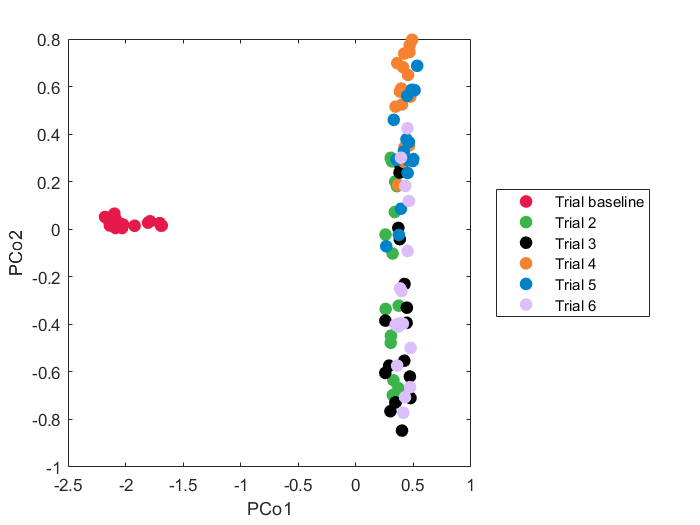

distances = 1 - proximities;
for subj=1:16
    distances(1+subj*6-6,:) = doublecentering(distances(1+subj*6-6,:));
end
rng(0);
[fin_b_tree_3_classes2,pcaParams,fin_prox,pr,coeff] = unsupervisedRF2(n_trees,distances,repmat(1:6,1,16),colors,true);

fin_dist = 1-fin_prox;
fin_dist = doublecentering(fin_dist);

% Run kernel PCA with polynomial kernel
kernel=Kernel('type', 'gaussian', 'gamma', 2);
parameter = struct('numComponents', 6, ...
                   'kernelFunc', kernel);
% build a KPCA object
kpca = KernelPCA(parameter);
% train KPCA model
rng(0);
kpca.train(fin_prox);

*** KPCA model training finished ***
running time            = 0.0175 seconds
kernel function         = gaussian 
number of samples       = 96 
number of features      = 96 
number of components    = 6 
number of T2 alarm      = 11 
number of SPE alarm     = 0 
accuracy of T2          = 88.5417% 
accuracy of SPE         = 100.0000% 


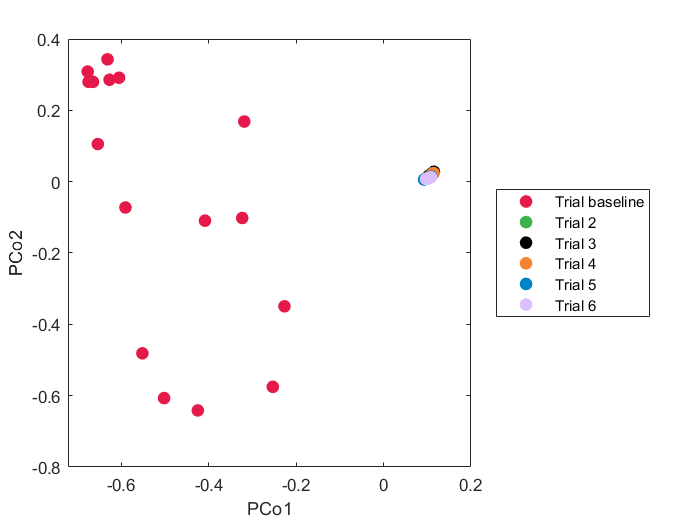


%　mapping data for kernel PCA plot
mappingData = kpca.score;

% mapping data for biplot
biMappingData=kpca.coefficient(:,1:3);

% Visualization 2D
figure; a=gscatter(mappingData(:,1),mappingData(:,2),repmat(1:6,1,16),colors,'o',7); %% I plot the outcomse of PCA analysis --> PCA scor eplot and I colorcode the samples with respect to class membership
xlabel('PCo1')
ylabel("PCo2")
set(a(1), 'markerfacecolor', colors(1,:));
set(a(2), 'markerfacecolor', colors(2,:));
set(a(3), 'markerfacecolor', colors(3,:));
set(a(4), 'markerfacecolor', colors(4,:));
set(a(5), 'markerfacecolor', colors(5,:));
set(a(6), 'markerfacecolor', colors(6,:));
legend('Trial baseline', 'Trial 2', 'Trial 3', 'Trial 4', 'Trial 5', 'Trial 6', 'Location', 'EastOutside')

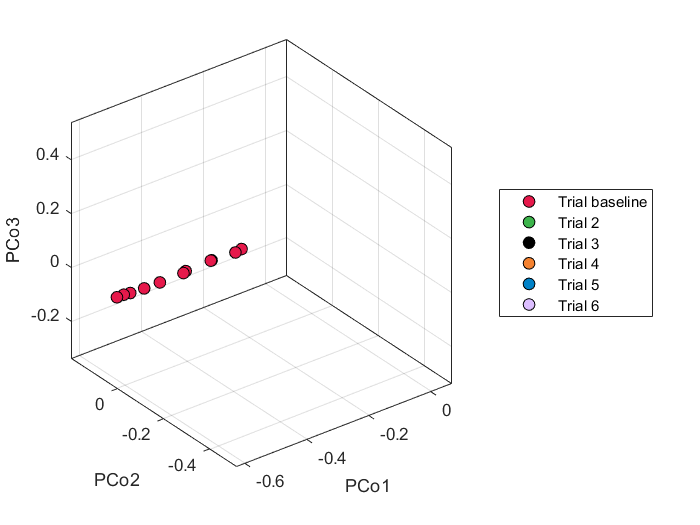


% Visualization 3D
figure; a=gscatter3(mappingData(:,1),mappingData(:,4),mappingData(:,3),repmat(1:6,1,16),{'k','k','k','k','k','k'},{'o','o','o','o','o','o'},7); %% I plot the outcomse of PCA analysis --> PCA scor eplot and I colorcode the samples with respect to class membership
xlabel('PCo1')
ylabel("PCo2")
zlabel("PCo3")
set(a(1), 'markerfacecolor', colors(1,:));
set(a(2), 'markerfacecolor', colors(2,:));
set(a(3), 'markerfacecolor', colors(3,:));
set(a(4), 'markerfacecolor', colors(4,:));
set(a(5), 'markerfacecolor', colors(5,:));
set(a(6), 'markerfacecolor', colors(6,:));
legend('Trial baseline', 'Trial 2', 'Trial 3', 'Trial 4', 'Trial 5', 'Trial 6', 'Location', 'EastOutside')